ans = 'scripts.imageViewer.gradationProcessor'

ans = 'scripts.imageViewer.gradationProcessor'

ans = 'scripts.imageViewer.gradationProcessor'

  opticalFlowProcess のプロパティ:

            baseFigure: [1×1 Figure]
             basePanel: [1×1 Panel]
              imgWidth: 384
             imgHeight: 384
             imgSource: [384×384×32 double]
        medianFiltered: [384×384×32 double]
             manualROI: []
            binaryMask: []
          manualROIImg: []
         binaryMaskImg: []
        opticalFlowImg: []
           fusionedImg: []
    medianFilteredView: [1×1 scripts.imageViewer.guiImageViewer]
         manualROIView: [1×1 scripts.imageViewer.guiImageViewer]
     binaryMaskImgView: [1×1 scripts.imageViewer.guiImageViewer]
       opticalflowView: [1×1 scripts.imageViewer.opticalFlowViewer]
       manualROIsetFig: []



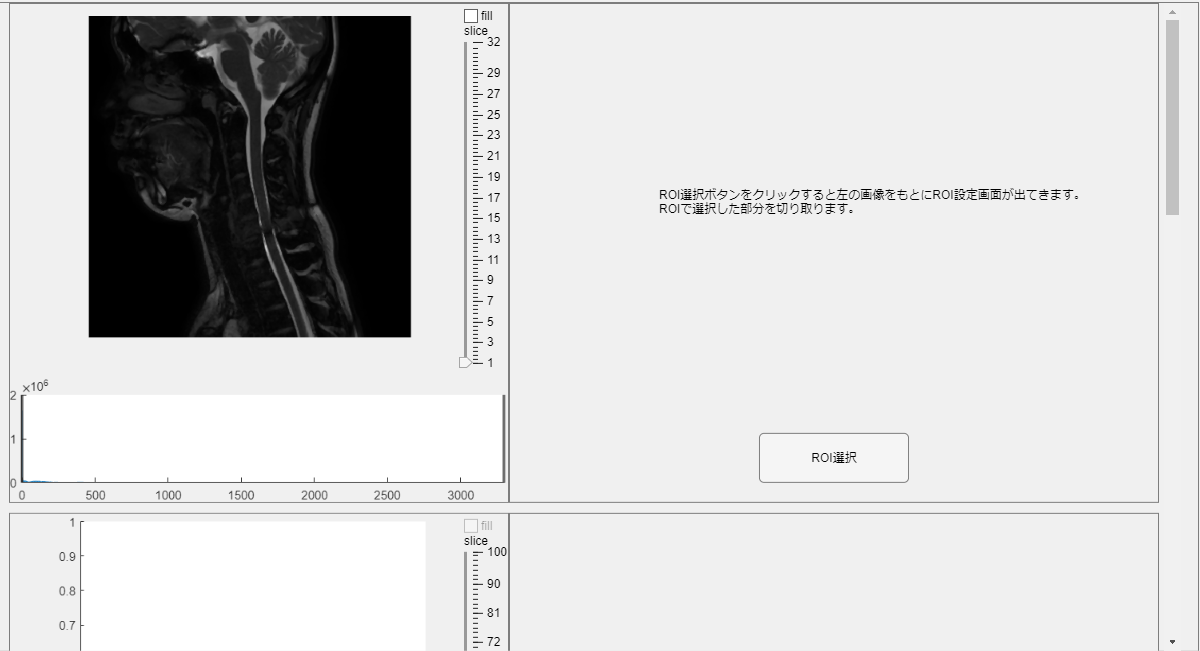

  opticalFlowProcess のプロパティ:

            baseFigure: [1×1 Figure]
             basePanel: [1×1 Panel]
              imgWidth: 384
             imgHeight: 384
             imgSource: [384×384×32 double]
        medianFiltered: [384×384×32 double]
             manualROI: []
            binaryMask: []
          manualROIImg: []
         binaryMaskImg: []
        opticalFlowImg: []
           fusionedImg: []
    medianFilteredView: [1×1 scripts.imageViewer.guiImageViewer]
         manualROIView: [1×1 scripts.imageViewer.guiImageViewer]
     binaryMaskImgView: [1×1 scripts.imageViewer.guiImageViewer]
       opticalflowView: [1×1 scripts.imageViewer.opticalFlowViewer]
       manualROIsetFig: []



clc
dcmHandler = scripts.dicomHandler.DICOMHandler();
dcmHandler.readDICOMDIR();
[dcmInfo, dcmImg] = dcmHandler.getPreview();
imgWidth = dcmInfo.Rows;
imgHeight = dcmInfo.Columns;
dcmImgs = dcmHandler.readAllImage();
opt = opticalFlowProcess( ...
    "image3D", dcmImgs, ...
    "imageWidth", imgWidth, ...
    "imageHeight", imgHeight);


%↑ができたら次はウィンドウ調整のMinMaxValidation